# **Finite Difference Time Domain (FDTD) Method in 1 Dimension**


$$\begin{array}{l}
{\textrm{Maxwell}}^{\prime } \mathrm{s}\;\textrm{Equations}\\
\;\;\;\;\;\;\;\;\;\;\nabla \cdot \mathbf{D}=\rho_f \;\;\;\;\;\;\;\;\;\;\nabla \cdot \mathit{\mathbf{B}}=0\;\;\;\;\;\;\;\;\;\;\nabla \times \mathbf{E}=-\frac{\partial \mathbf{B}}{\partial t}\;\;\;\;\;\;\;\;\;\;\nabla \times \mathbf{H}={\mathbf{J}}_f +\frac{\partial \mathbf{D}}{\partial t}\\
\textrm{For}\;1\mathrm{D}\;\textrm{variation}\;\textrm{of}\;\textrm{the}\;\textrm{fields},\;\textrm{assume}\;\mathbf{E}=E_z \left(x,t\right)\;\hat{z} \;\;\;\;\textrm{and}\;\;\;\mathbf{H}=H_y \left(x,t\right)\;\hat{y} \ldotp \;\textrm{Rewrite}\;\textrm{the}\;\textrm{curl}\;\textrm{equations}:\\
\;\;\;\;\;\;\;\;\;\;\mu \frac{\partial H_y }{\partial t}=\frac{\partial E_z }{\partial x}\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\epsilon \frac{\partial E_z }{\partial t}=\frac{\partial H_y }{\partial x}-J_z \\
\textrm{Discretize}\;\textrm{the}\;\textrm{equations}\;\textrm{by}\;\textrm{introducing}\;\mathrm{a}\;\textrm{staggered}\;\textrm{grid}\;\textrm{with}\;\textrm{the}\;H\;\textrm{field}\;\textrm{nodes}\;\textrm{displaced}\;\textrm{by}\;\mathrm{a}\;\textrm{half}\;\textrm{step}\;\textrm{in}\;\textrm{space}\;\textrm{and}\;\textrm{time}\ldotp \\
\;\;\;\;\;\;\;\;\;\;x=m\Delta_x \;\;\;{t=q\Delta }_t \\
{\;\;\;\;\;\;\;\;\;\;H}_y^{q+\frac{1}{2}} \left\lbrack m+\frac{1}{2}\right\rbrack =H_y^{q-\frac{1}{2}} \left\lbrack m+\frac{1}{2}\right\rbrack +\frac{\Delta_t }{\mu \Delta_x }\left(E_z^q \left\lbrack m+1\right\rbrack -E_z^q \left\lbrack m\right\rbrack \right)\\
{\;\;\;\;\;\;\;\;\;\;E}_z^{q+1} \left\lbrack m\right\rbrack =E_z^q \left\lbrack m\right\rbrack +\frac{\Delta_t }{\epsilon \Delta_x }\left(H_y^{q+\frac{1}{2}} \left\lbrack m+\frac{1}{2}\right\rbrack -H_y^{q+\frac{1}{2}} \left\lbrack m-\frac{1}{2}\right\rbrack \right)-\frac{\Delta_t }{\epsilon }J_z^{q+\frac{1}{2}} \left\lbrack m\right\rbrack \\
\textrm{Rewrite}\;\textrm{the}\;\textrm{coefficients}:\;\;\;\;\;\;\;\;\frac{\Delta_t }{\mu \Delta_x }=\frac{1}{\mu_r \eta_0 }S_c \;\;\;\;\;\;\;\;\;\;\frac{\Delta_t }{\epsilon \Delta_x }=\frac{\eta_0 }{\epsilon_r }S_c \;\;\;\;\\
{\;\;\;\;\;\;\;\;\;\;\textrm{where}\;\;\;\eta }_0 =\sqrt{\mu_0 \;/\;\epsilon_0 }\approx 377\;\Omega \;\;\left(\textrm{impedance}\;\textrm{of}\;\textrm{free}\;\textrm{space}\right)\;\;\textrm{and}\;\;S_c =c\Delta_t /\Delta_x \;\;\;\left(\textrm{Courant}\;\textrm{number}\right)\\
\textrm{Let}\;\;S_c =1,\epsilon_r =1,\mu_r =1\ldotp \\
\textrm{Let}\;\textrm{the}\;\textrm{current}\;\textrm{source}\;J_z \;\textrm{be}\;\mathrm{a}\;\textrm{Gaussian}\;\textrm{pulse}\;\textrm{with}\;\textrm{maximum}\;\textrm{at}\;q=30\ldotp \;\textrm{It}\;\textrm{occurs}\;\textrm{at}\;\mathrm{a}\;\textrm{single}\;\textrm{node}\;\left(m=50\right)\ldotp \\
\textrm{Reference}:\textrm{Schneider},J,\;\textrm{"Understanding}\;\textrm{the}\;\textrm{Finite}\;\textrm{Difference}\;\textrm{Time}\;\textrm{Domain}\;\textrm{Method"}\;\left(2021\right)
\end{array}$$
       

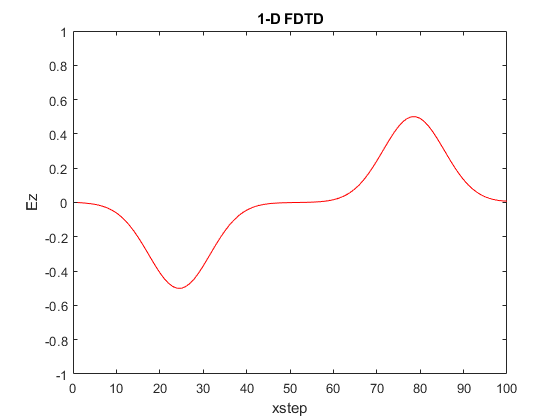

tsteps = 500;
xsteps = 100;
imp0 = 377;     % impedance of free space
%initialize the magnetic and electric field arrays
Hy = zeros(1,xsteps);
Ez = zeros(1,xsteps);
% time step loop
for q = 1:tsteps  
    % update the magnetic field
    for m = 1:(xsteps-1)
        Hy(m) = Hy(m) + (Ez(m+1) - Ez(m))/imp0;
    end
    %update the electric field
    for m = 2:xsteps
        Ez(m) = Ez(m) + (Hy(m) - Hy(m-1))*imp0;
    end
    % 50th node is source of Gaussian pulse
    Ez(50) = Ez(50) + exp(-(q-30)^2/100);
    if mod(q,2) == 0
        plot(1:xsteps,Ez,'r');
        title("1-D FDTD");
        xlabel("xstep");
        ylabel("Ez");
        axis([0 xsteps -1 1]);
        drawnow;
    end
end